## Get Data

clear 
CSV_NAME = "96dB.csv";
file = readtable(CSV_NAME,'VariableNamingRule','preserve');

data = table2array(file(:,2));
data(end) = [];         %% remove the last value;

## Sorted data with **phase order**

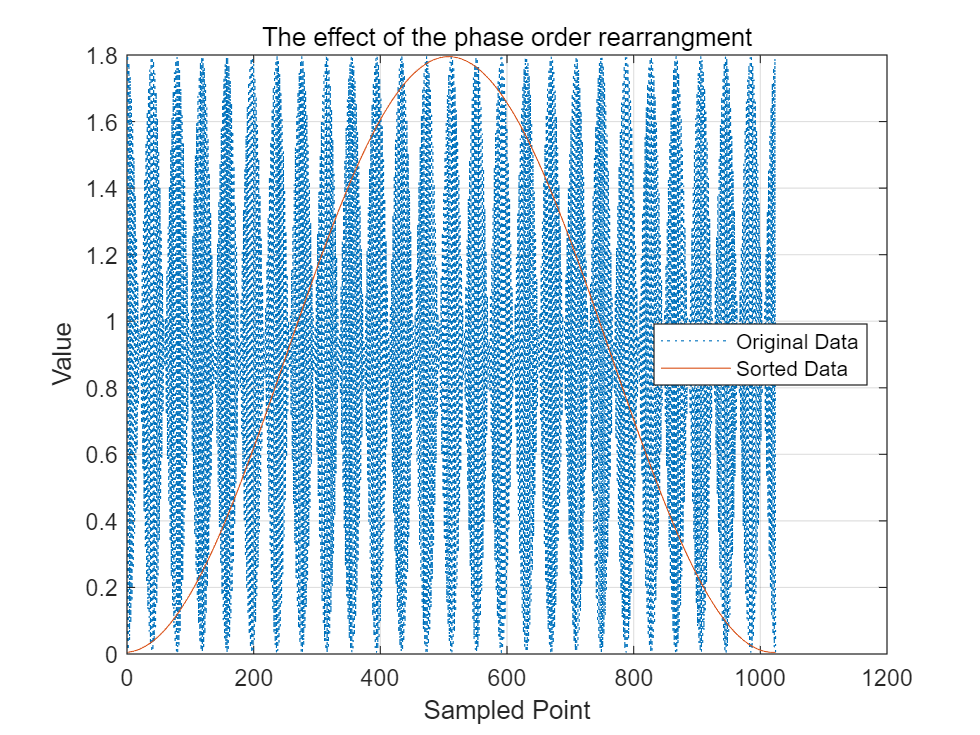

Fs = 10E6;
Fi = 499 / 1024 * Fs;
N = 1024;

T = PhaseOrder(data, Fi, Fs);

figure
plot(data, ':');
hold on;
plot(T.Value);
grid on;
box on;
xlabel("Sampled Point");
ylabel("Value");
title("The effect of the phase order rearrangment");
legend(["Original Data", "Sorted Data"], "Location","best");

## FFT Comparsion

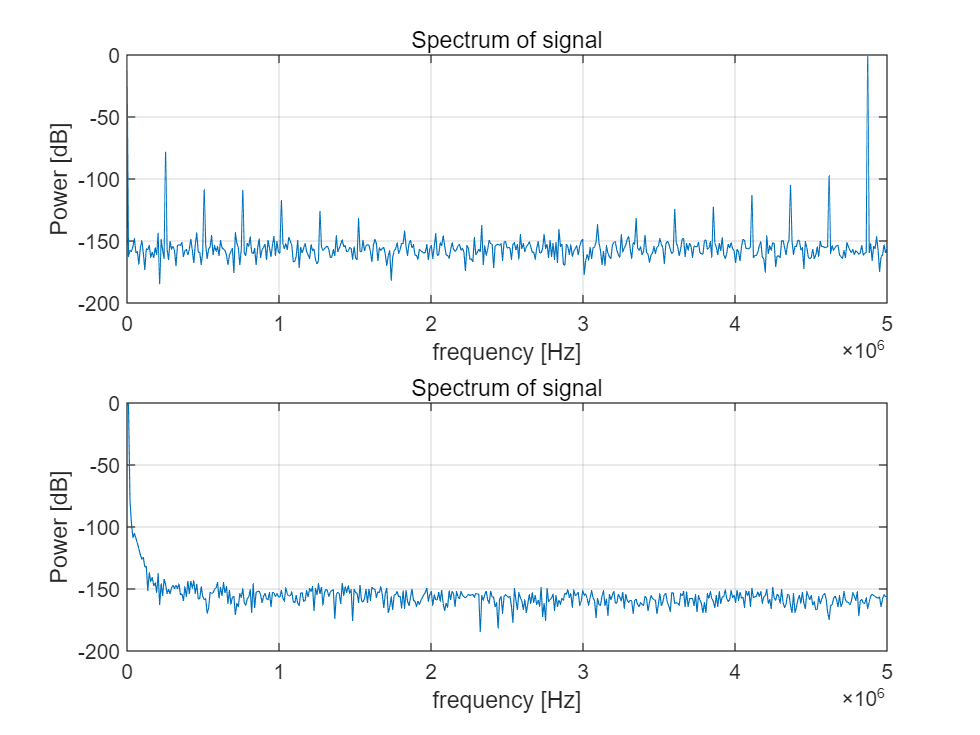

T.FFT = fft(T.Value);

[f, P] = PlotSpectrum([data, T.Value], Fs);

## Find out base and harmonic component

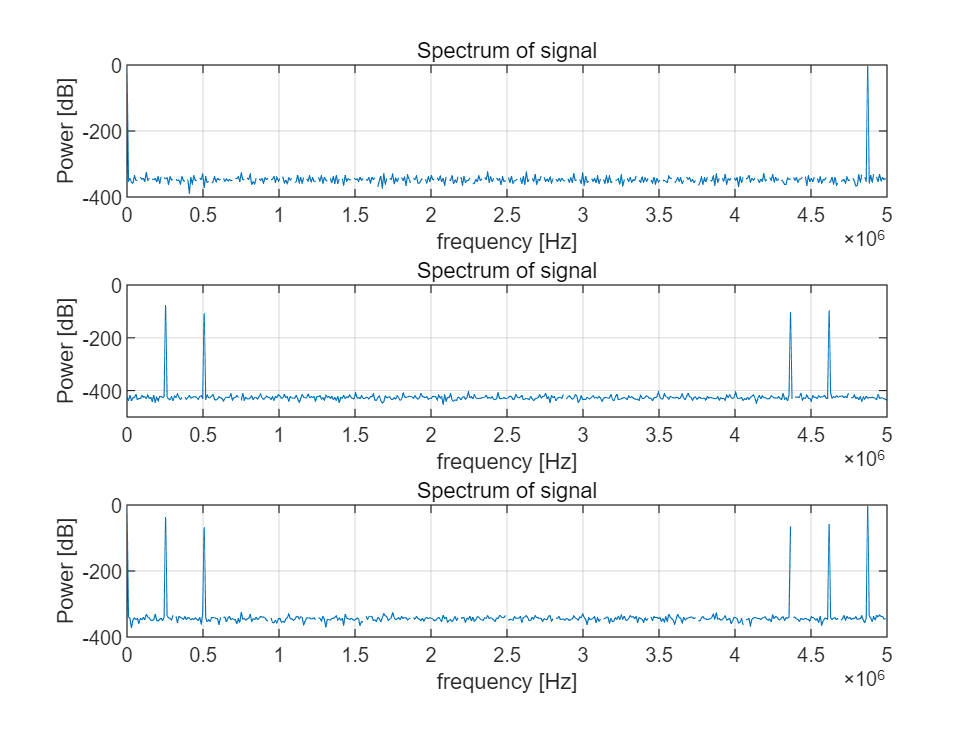

NumHarmonic = 4;

weighted = zeros(N, 1);
weighted([1,2,end]) = 1;

T.FFTBase = T.FFT .* weighted;
T.ValueBase = ifft(T.FFTBase);

weighted = zeros(N, 1);
weighted(3:3+NumHarmonic-1) = 1;
weighted(end-NumHarmonic:end-1) = 1;

T.FFTHarm = T.FFT .* weighted;
T.ValueHarm = ifft(T.FFTHarm);

% Amplifier harmonic component
AF = 100;
T.FFTFinal = T.FFTBase + AF*T.FFTHarm;
T.ValueFinal = ifft(T.FFTFinal);

% Check the filter effect
Ttem = sortrows(T, "Index");
[f, P] = PlotSpectrum([Ttem.ValueBase, Ttem.ValueHarm, Ttem.ValueFinal], Fs);

## Plot wave

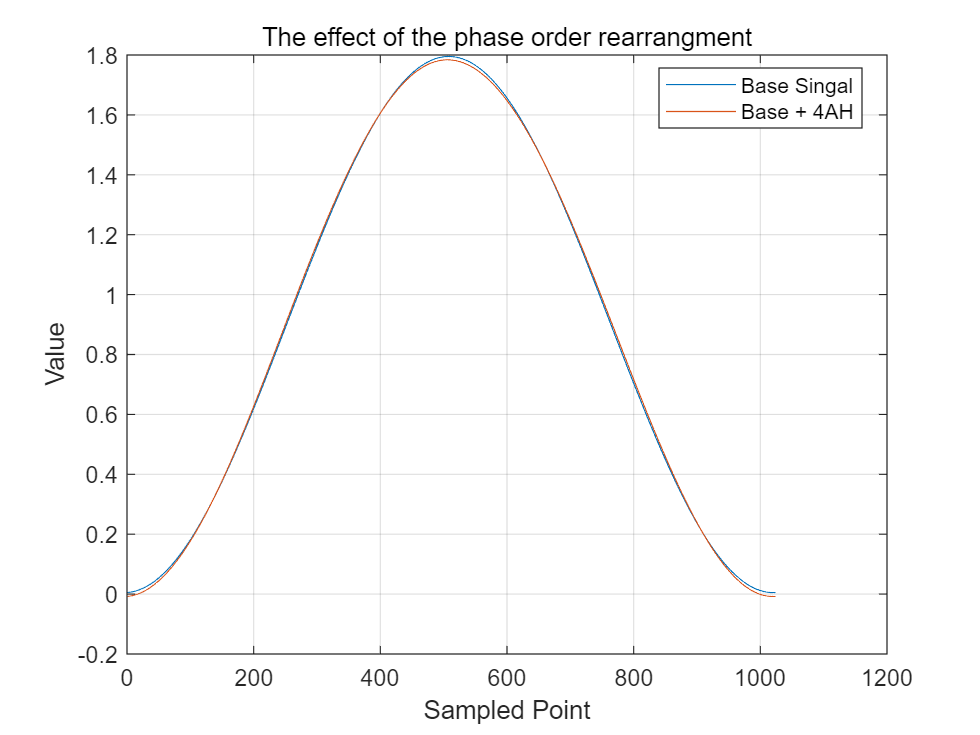

figure
plot(T.ValueBase);
hold on;
% plot(ifft(T.FFTBase + T.FFTHarm));
plot(T.ValueFinal);
grid on;
box on;
xlabel("Sampled Point");
ylabel("Value");
title("The effect of the phase order rearrangment");
legend(["Base Singal", "Base + 4AH"], "Location","best");